data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);

%dates = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');

Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);
Total_Population = (Confounding.TOT_POP);

cases = table2array(data(:,12:173));
cases = cases./Total_Population;

% dates = table2array(dates(1,[12:173]));
% dates = datetime(dates, 'Format', 'dd/MM/yy'); 

splines = zeros(842,1024);

for t = 1:842
    casesS = cases(t,:);
    casesS = nonzeros(casesS); % non-zero cases 
    if length(casesS)>1
        x = [1:length(casesS)]';  % number of days since first case 
        f = fit(x, casesS, 'smoothingspline');
        xeval = linspace(1, length(casesS), 1024);
        sp_eval = f(xeval)';
        splines(t,:)= sp_eval;
    end 
end 

splines1 = splines(:,[1:256]);
splines2 = splines(:,[257:512]);
splines3 = splines(:,[513:768]);
splines4 = splines(:,[769:1024]);

% Power Spectral Density Computations 
Fs = 100; 

x = splines; 
[~,l] = size(x);
Psd = periodogram(x',rectwin(l),l,Fs)';
%Psd_DBHZ =(10*log10(Psd));
Psd_DBHZ =Psd;
freq = 0:Fs/l:Fs/2;

x1 = splines1; 
[~,l1] = size(x1);
Psd1 = periodogram(x1',rectwin(l1),l1,Fs)';
%Psd_DBHZ1 = (10*log10(Psd1));
Psd_DBHZ1 = Psd1;
freq1 = 0:Fs/l1:Fs/2;

x2 = splines2; 
[~,l2] = size(x2);
Psd2 = periodogram(x2',rectwin(l2),l2,Fs)';
%Psd_DBHZ2 = (10*log10(Psd2));
Psd_DBHZ2 = Psd2;
freq2 = 0:Fs/l2:Fs/2;

x3 = splines3; 
[~,l3] = size(x3);
Psd3 = periodogram(x3',rectwin(l3),l3,Fs)';
%Psd_DBHZ3 = (10*log10(Psd3));
Psd_DBHZ3 = Psd3;
freq3 = 0:Fs/l3:Fs/2;

x4 = splines4; 
[~,l4] = size(x4);
Psd4 = periodogram(x4',rectwin(l4),l4,Fs)';
%Psd_DBHZ4 = (10*log10(Psd4));
Psd_DBHZ4 = Psd4;
freq4 = 0:Fs/l4:Fs/2;

[bin_idx, bins] = frequency_bins(freq);
bin_sums = PSD_bsums(bin_idx, Psd_DBHZ); 

[bin_idx1, bins1] = frequency_bins(freq1);
bin_sums1 = PSD_bsums(bin_idx1, Psd_DBHZ1); 

[bin_idx2, bins2] = frequency_bins(freq2); 
bin_sums2 = PSD_bsums(bin_idx2, Psd_DBHZ2);

[bin_idx3, bins3] = frequency_bins(freq3); 
bin_sums3 = PSD_bsums(bin_idx3, Psd_DBHZ3);

[bin_idx4, bins4] = frequency_bins(freq4); 
bin_sums4 = PSD_bsums(bin_idx4, Psd_DBHZ4);

clf; 
i = 333;

TS1 = splines1(i,:);
s1 = sum(TS1.^2);
TS2 = splines2(i,:);
s2 = sum(TS2.^2);
TS3 = splines3(i,:);
s3 = sum(TS3.^2);
TS4 = splines4(i,:);
s4 = sum(TS4.^2);
TSS = sum([s1, s2, s3, s4]);

s1N = s1/TSS

s1N = 0.0178

s2N = s2/TSS

s2N = 0.1999

s3N = s3/TSS

s3N = 0.3483

s4N = s4/TSS

s4N = 0.4339

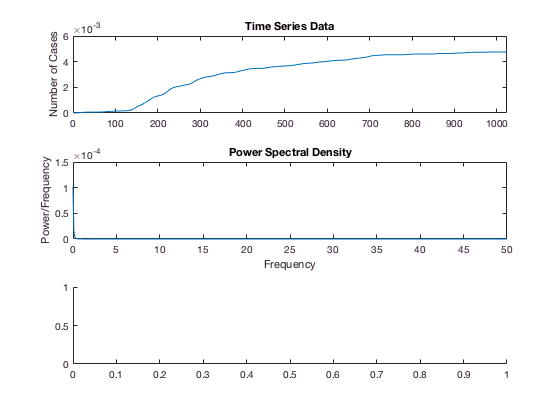


figure(1)
%suptitle(data.Combined_Key(i))

subplot(3,1,1)
plot(x(i,:))
xlim([0,1024])
title('Time Series Data')
ylabel('Number of Cases')

subplot(3,1,2)
plot(freq, Psd_DBHZ(i,:))
title('Power Spectral Density')
xlabel('Frequency')
ylabel('Power/Frequency')

subplot(3,1,3)
X = categorical({'0-100', '100-200', '200-300', '300-400', '400-500', '500-600', '600-700', '700-800', '800-900', '900-1000'});
X = reordercats(X,{'0-100', '100-200', '200-300', '300-400', '400-500', '500-600', '600-700', '700-800', '800-900', '900-1000'});
Y = bin_sums(i,:);

[~,idx] = max(Y);
YM = zeros(size(Y));
YM(idx) = Y(idx);

hold on;

b = bar(X,Y,'FaceColor',[0 0.4470 0.7410]);

Error using bar (line 143)
X must be same length as Y.

bM = bar(X, YM, 'FaceColor', [0.4660 0.6740 0.1880]);
hold off; 

title('Power Spectral Density Bins')
xlabel('Bin Edges')
ylabel('Power per Bin')

%clf;
figure(2)
Psd_A4 = [Psd_DBHZ1(i,:), Psd_DBHZ2(i,:), Psd_DBHZ3(i,:), Psd_DBHZ4(i,:)];
Psd_A4_Min = min(Psd_A4);
Psd_A4_Max = max(Psd_A4);

subplot(2,4,1)
plot(freq1, Psd_DBHZ1(i,:))
%title('Power Spectral Density')
ylim([Psd_A4_Min,Psd_A4_Max])
xlabel('Frequency')
ylabel('Power/Frequency')

subplot(2,4,2)
plot(freq2, Psd_DBHZ2(i,:))
ylim([Psd_A4_Min,Psd_A4_Max])
%title('Power Spectral Density')
xlabel('Frequency')
%ylabel('Power/Frequency (dB/Hz)')

subplot(2,4,3)
plot(freq3, Psd_DBHZ3(i,:))
ylim([Psd_A4_Min,Psd_A4_Max])
%title('Power Spectral Density')
xlabel('Frequency')
%ylabel('Power/Frequency (dB/Hz)')

subplot(2,4,4)
plot(freq4, Psd_DBHZ4(i,:))
ylim([Psd_A4_Min,Psd_A4_Max])
%title('Power Spectral Density')
xlabel('Frequency')
%ylabel('Power/Frequency (dB/Hz)')

TP1 = sum(bin_sums1(i,:))
TP2 = sum(bin_sums2(i,:))
TP3 = sum(bin_sums3(i,:))
TP4 = sum(bin_sums4(i,:))

t = sum([TP1, TP2, TP3, TP4]);
TP1/t
TP2/t
TP3/t
TP4/t

X = categorical({'1st Quarter', '2nd Quarter', '3rd Quarter', '4th Quarter'});
X = reordercats(X,{'1st Quarter', '2nd Quarter', '3rd Quarter', '4th Quarter'});

subplot(2,4,[5:8]);
Y = [TP1, TP2, TP3, TP4];

YM = zeros(size(Y));
[~, idx] = max(Y);
YM(idx) = Y(idx);

hold on; 
b = bar(X,Y,'FaceColor',[0 0.4470 0.7410]);
bM = bar(X, YM, 'FaceColor', [0.4660 0.6740 0.1880]);
hold off; 

% 
% 
% X = categorical({'0-100', '100-200', '200-300', '300-400', '400-500', '500-600', '600-700', '700-800', '800-900', '900-1000'});
% X = reordercats(X,{'0-100', '100-200', '200-300', '300-400', '400-500', '500-600', '600-700', '700-800', '800-900', '900-1000'});
% 
% subplot(2,4,5)
% TP1 = sum(bin_sums1(i,:))
% Y1 = bin_sums1(i,:);
% 
% [~,idx1] = max(Y1);
% YM1 = zeros(size(Y1));
% YM1(idx1) = Y1(idx1);
% 
% hold on;
% b = bar(X,Y1,'FaceColor',[0 0.4470 0.7410]);
% bM = bar(X, YM1, 'FaceColor', [0.4660 0.6740 0.1880]);
% hold off; 
% 
% %title('Power Spectral Density Bins')
% xlabel('Bin Edges')
% ylabel('Power per Bin')
% 
% subplot(2,4,6)
% TP2 = sum(bin_sums2(i,:))
% Y2 = bin_sums2(i,:);
% 
% [~,idx2] = max(Y2);
% YM2 = zeros(size(Y2));
% YM2(idx2) = Y2(idx2);
% 
% hold on;
% b = bar(X,Y2,'FaceColor',[0 0.4470 0.7410]);
% bM = bar(X, YM2, 'FaceColor', [0.4660 0.6740 0.1880]);
% hold off; 
% 
% %title('Power Spectral Density Bins')
% xlabel('Bin Edges')
% %ylabel('Power per Bin')
% 
% subplot(2,4,7)
% TP3 = sum(bin_sums3(i,:))
% Y3 = bin_sums3(i,:);
% 
% [~,idx3] = max(Y3);
% YM3 = zeros(size(Y3));
% YM3(idx3) = Y3(idx3);
% 
% hold on;
% b = bar(X,Y3,'FaceColor',[0 0.4470 0.7410]);
% bM = bar(X, YM3, 'FaceColor', [0.4660 0.6740 0.1880]);
% hold off; 
% 
% %title('Power Spectral Density Bins')
% xlabel('Bin Edges')
% %ylabel('Power per Bin')
% 
% subplot(2,4,8)
% TP4 = sum(bin_sums4(i,:))
% Y4 = bin_sums4(i,:);
% 
% [~,idx4] = max(Y4);
% YM4 = zeros(size(Y4));
% YM4(idx4) = Y4(idx4);
% 
% hold on;
% b = bar(X,Y4,'FaceColor',[0 0.4470 0.7410]);
% bM = bar(X, YM4, 'FaceColor', [0.4660 0.6740 0.1880]);
% hold off; 
% 
% %title('Power Spectral Density Bins')
% xlabel('Bin Edges')
% %ylabel('Power per Bin')

function [bin_idx, bins] = frequency_bins(freq) 
    max_F = max(freq);
    bin_idx = [];
    bins = [];
    for i = 0:100:max_F
        test = freq>=i;
        t = find(test);
        bin_idx = [bin_idx, t(1)];
        bins = [bins, i];
    end 
end 

function [sums] = PSD_bsums(bin_idx, psd)
    [u,~] = size(psd);
    sums = zeros(u,length(bin_idx)-1);
    for i=1:length(bin_idx)-1
        if i == length(bin_idx)-1
            low = bin_idx(i);
            high = bin_idx(i+1);
            sect = psd(:,low:high);
            s = sum(sect,2);
            sums(:,i) = s;
        else
            low = bin_idx(i);
            high = bin_idx(i+1)-1;
            sect = psd(:,low:high);
            s = sum(sect,2);
            sums(:,i) = s;
        end 
    end 
end 